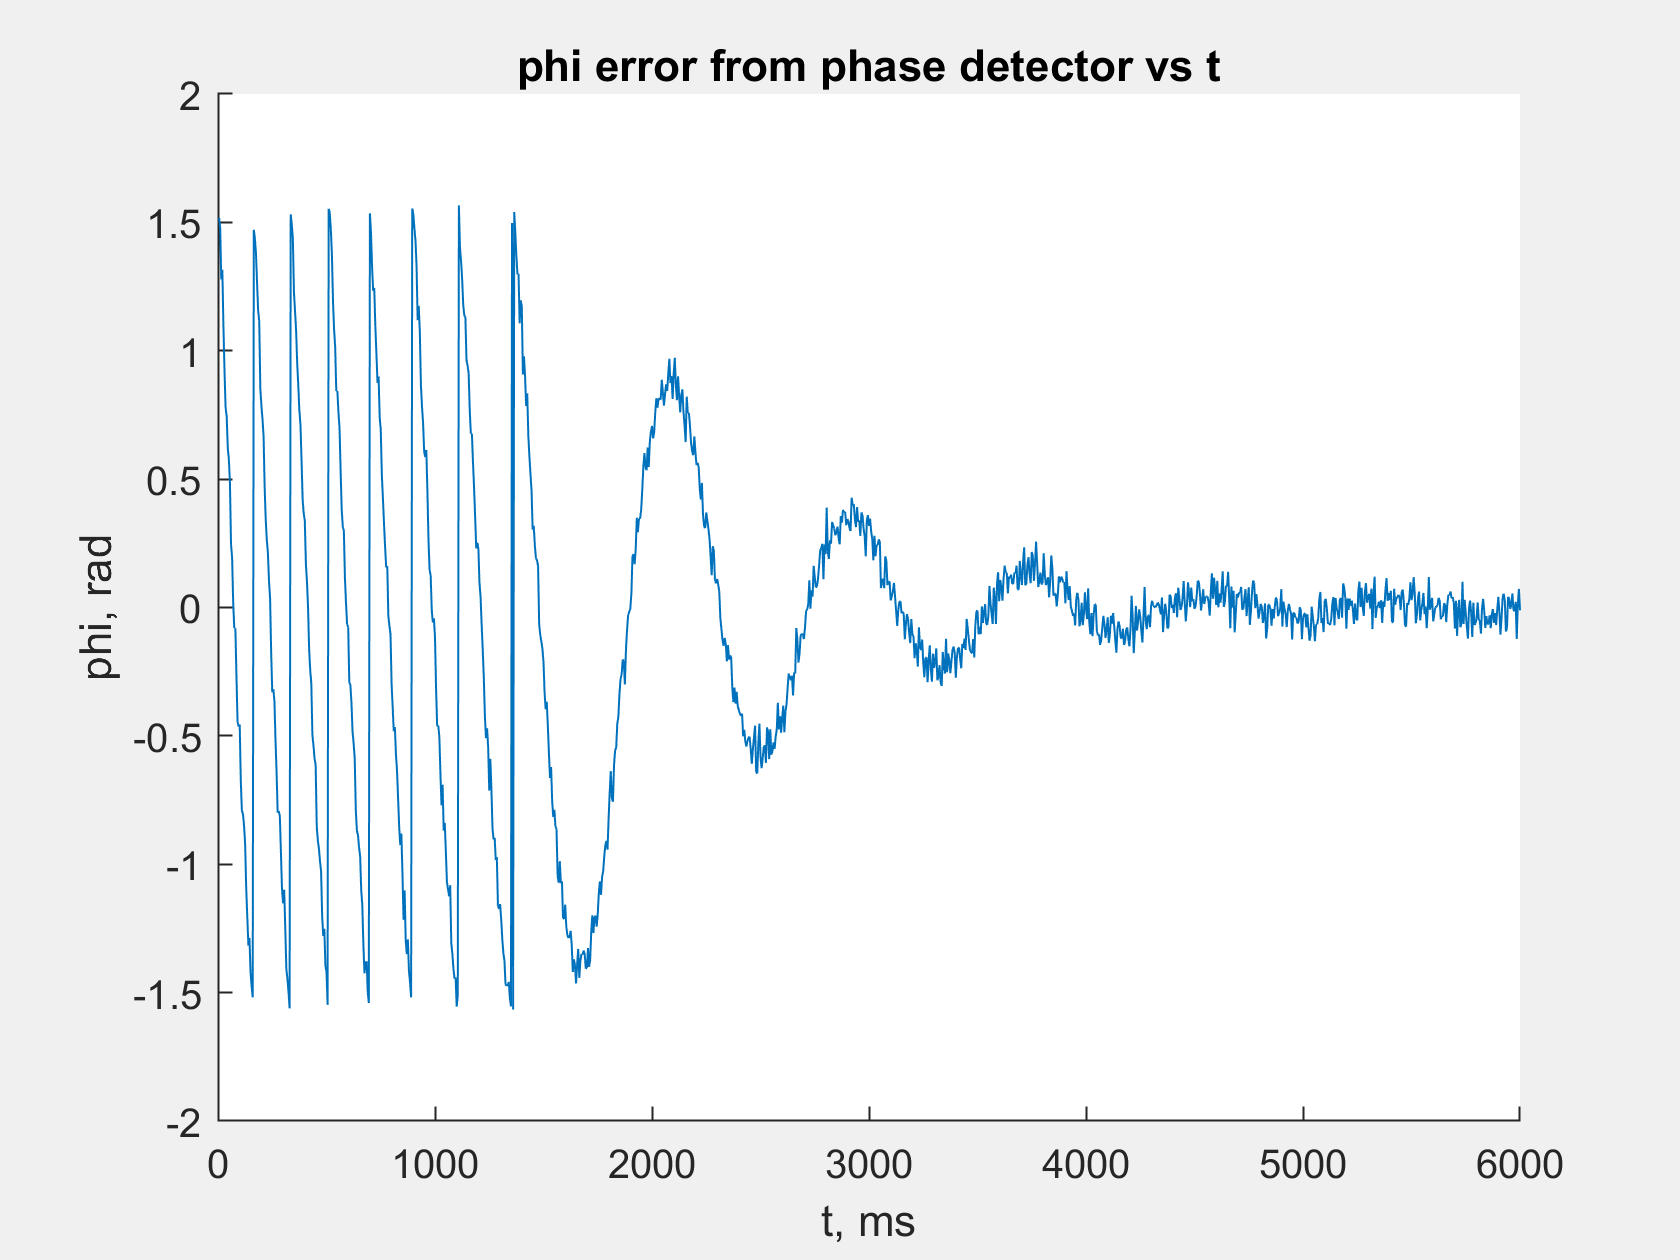

satellite_list = [7];

phi_array = load ("phi_log.mat").phi_log;
loop_filter_output_array = load ("delta_f_log.mat").delta_f_log;

max_index = length (phi_array);
%max_index = 500;

phi_array = phi_array (:, 1 : max_index);
loop_filter_output_array = loop_filter_output_array (:, 1 : max_index);
t_values = integrate_periods * linspace (1, max_index, max_index);

% phi plot
fig_phi = figure;
set (fig_phi, 'Visible', 'on');
hold on;

for satellite_index = satellite_list
    plot (t_values, phi_array (satellite_index, :), '-');
end

xlabel ('t, ms');
ylabel ('phi, rad');
title ('phi error from phase detector vs t');
hold off;

savefig (fig_phi, 'phi(t).fig');
saveas (fig_phi, 'phi(t).jpeg');

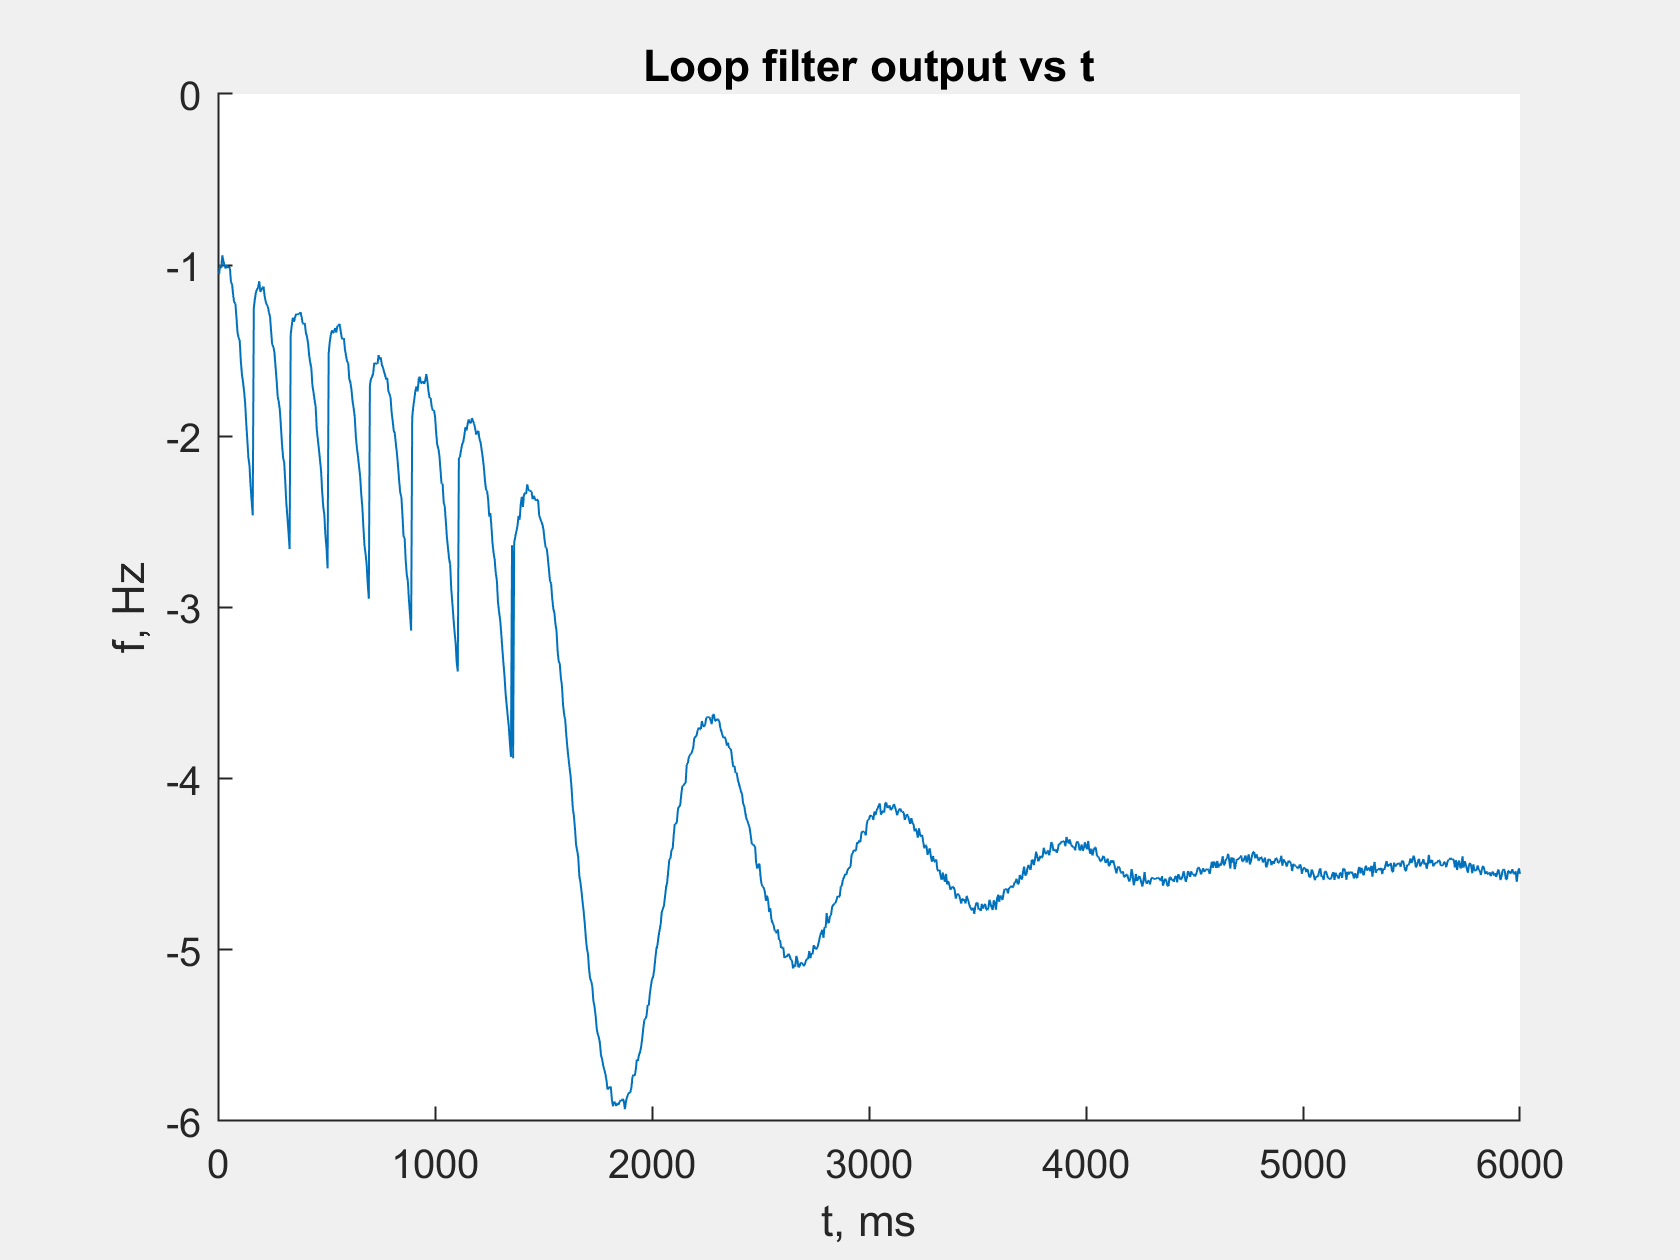


% Loop filter output plot
fig_loop_filter = figure;
set (fig_loop_filter, 'Visible', 'on');
hold on;

for satellite_index = satellite_list
    plot (t_values, loop_filter_output_array (satellite_index, :), '-');
end

xlabel ('t, ms');
ylabel ('f, Hz');
title ('Loop filter output vs t');
hold off;

savefig (fig_loop_filter, 'f(t).fig');
saveas (fig_loop_filter, 'f(t).jpeg');